# Arrays

[⇦ Overview](NavigationOverview.mlx)

Both doubles and strings are *scalar* data structures in MATLAB because they represent single values. Many programs require more than a single value to work with. This lead programmers to the concept of an array as a collection of indexed values. A vector of data might track something like the temperature at a weather station over the course of time. A matrix could include columns for each tracked value of temperature, humidity, precipitation, and barometric pressure at each time. If you wish to track several values over time at multiple weather stations, then you would require a 3-D array indexed by the time, the weather variable, and the weather station identifier. 

[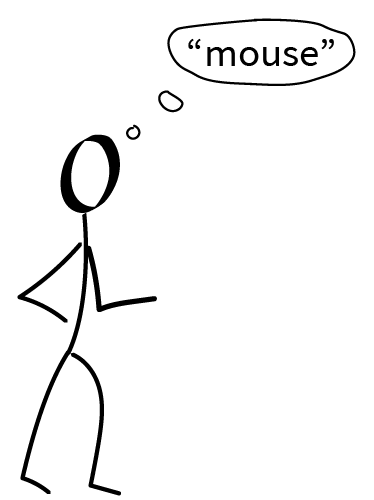](matlab:open('./Arrays.mlx'))   [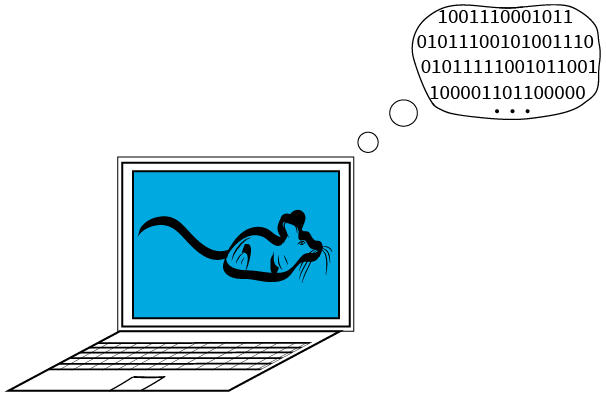](matlab:open('./Arrays.mlx'))

This script will introduce vectors, matrices, and 3-dimensional arrays.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB, as concepts and commands are introduced together, but some familiarity with the Live Editor environment was introduced in [Introduction.mlx](matlab:open('./Introduction.mlx')). 

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running all code blocks.

## Compound Data Structures

### Vectors

A *vector *of values is a one-dimensional indexed list of elements that may be arranged either horizontally (a row vector) such as the example

% run this code
daysOfWeek = ["Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday" "Sunday"]

or vertically (a column vector) such as the example

ordinals = ["first";"second";"third";"fourth";"fifth"]

Notice that each vector is labeled with a pair of numbers. The row vector is called a `1x7 string` because it has 1 row and 7 columns, each containing a [string element](matlab:open('./Data.mlx')). The column vector is called a `5x1 string` because it contains 5 rows and 1 column, each containing a string element. In general, each element in a vector must be the same type of data. We can make a column vector containing [doubles](matlab:open('./Data.mlx')):

nums = [6;7]

and even concatenate vectors together along a matching dimension:

newVector = [ordinals;nums]

But if the programming language allows this to happen, it will enforce a common type for every element of the result. In the example of `newVector` that means the elements that had been doubles in `nums` become strings in `newVector`.

#### Indexing

Recall that a vector was identified as a one-dimensional *indexed* list of elements. This means that, as a programmer, you can access a single element (or range of elements) in a vector by identifying them by index (that is by number) in the list.

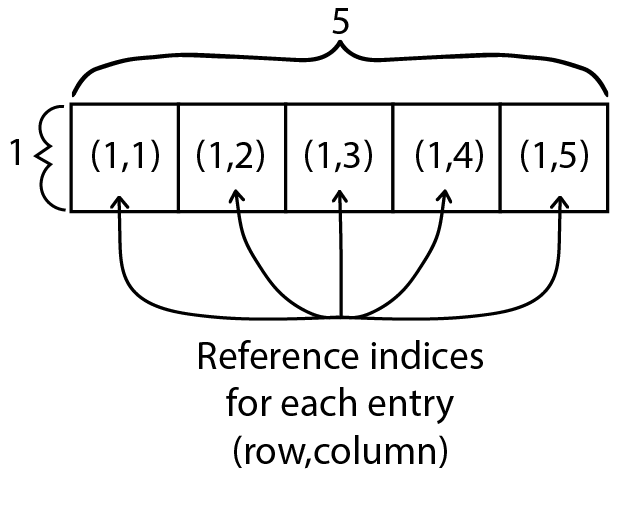

Programming languages differ in their indexing, but they either start indexing elements with 1 (such as MATLAB and R) or 0 (such as Python). Since there is only one changing index in a vector (either the column index for row vectors or the row index for column vectors) that single index is sufficient to uniquely identify the entry. 

% run this code
daysOfWeek(5)
ordinals(2:4)
k = 3;
"The " + ordinals(k) + " day of the week is " + daysOfWeek(k) + "."

  **Try**. 

- Run the code below. 

- Then run the code without transposing `daysOfWeek`. What is different? 

- What does the `transpose()` function do? How can you figure it out?

- What happens if you run the command to set the value of `allDays` with `newVector` instead of `ordinals`? Or with `daysOfWeek` instead of `daysOfWeek(1:5)`? Or both? 

allDays = "The " + ordinals + " day of the week is " + transpose(daysOfWeek(1:5)) + "."

  **Pro-tip**. Another way to find the transpose of a matrix `M` in MATLAB is to write `M'`.

#### Vector Addition

Vector addition requires that the vectors in question be of the same dimension. If the dimensions are identical, the operation proceeds term-wise with each element being added to the element with the same index in the other matrix. 

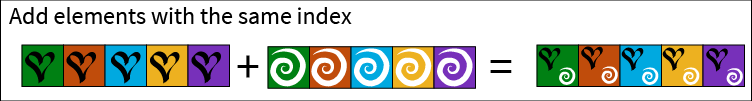

As in the case of concatenation of `string` types and `double` types resulting in `string` values as output, MATLAB is designed to change your data structures if it is necessary to execute a command. In the case of

allDays = "The " + ordinals + " day of the week is " + transpose(daysOfWeek(1:5)) + "."

it is necessary to expand the `1x1` vectors `"The"` and `" day of the week is "` and "." to be `5x1` vectors, just like `ordinals` and `daysOfWeek(1:5)` as shown:

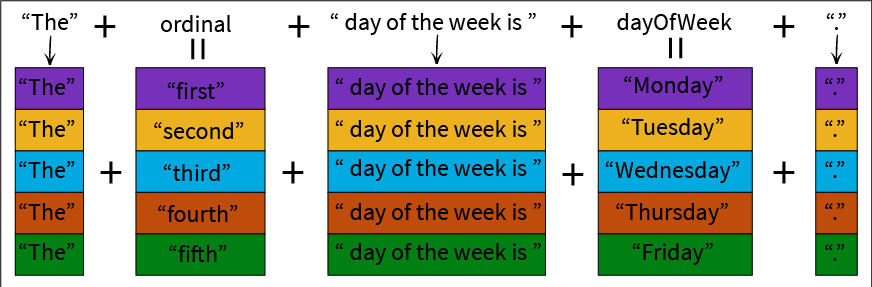

Concatenating each element with its corresponding index values (in this case, matching color) in the other vectors, the result is a new `5x1` vector of strings.

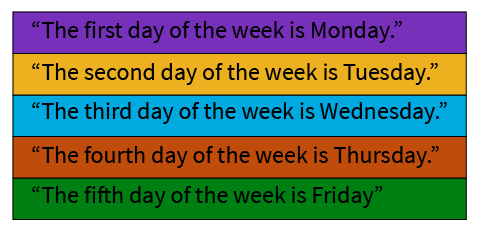

 **Reflect**.

- Vector operations can be extremely effective, but you can also accidentally perform a very different operation than you intended. How can you check whether you have, in fact, performed the operation you meant? 

- What do you think will happen if you perform other mathematical operations involving numeric vectors? Are there any standard patterns to what works as you expect and what does not?

**Example: Mathematical operations on numerical vectors**

vec1 = [1 2 3 4 5]


### Matrices

A matrix is a 2-dimensional collection of $mn$ elements arranged in `m` rows and `n` columns, such that the `(i,j)`th element is in the `i`th row and `j`th column.  

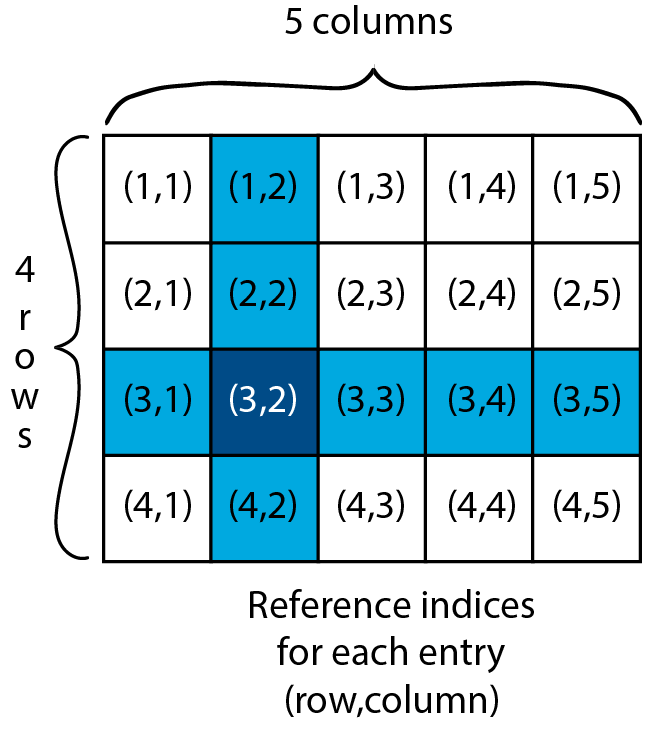

While every vector is trivially a matrix, the result of `vec7` in the Reflection examples above is a more standard `5x5` matrix. 

#### Matrix Multiplication

As you saw in the Example above, vector multiplication can sometimes result in a significantly larger matrix as output. This is because the `i`th row of the first matrix has to be multiplied term-wise with the `j`th column of the second matrix and then those values are summed to determine the value in the `(i,j)`th position in the output matrix. 

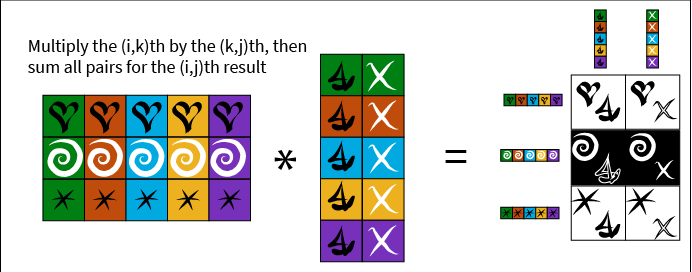

** Exercise 1**.

Use the diagram of matrix multiplication to explain the dimensions and values in the computed result

vec1 = [1 2 3 4 5];
vec7 = transpose(vec1)*vec1

and here

vec2 = [vec1; vec1];
vec3 = [vec1', vec1'];
vec4 = vec2 * vec3

**Note: **One novel property of matrix multiplication is that it is NOT commutative. In the figure above, there is a `3x5` matrix multiplied by a `5x2` matrix to result in a `3x2` matrix. If we try to compute a `5x2` matrix multiplied by a `3x5` matrix, we can't even get started because the top row (sailboat, X) doesn't contain the same number of elements as the first column (heart, swirl, star) and so cannot possibly be multiplied term-wise.

#### Using Matrices to Organize Information

Although matrices are mathematical objects, as a two-dimensional array data structure they can be used to collect, organize, and analyze data of nearly any type. 

Consider the matrix `simpIm0` given by

simpleIm0 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

  **Try**.

- What do you think the matrix `simpleIm0` might be encoding? 

- Try interpreting the matrix as an image. What do you see?

% Interpret simpleIm0 as an image and scale it to a visible size
imshow(simpleIm0,"InitialMagnification",1000)

        3. What will happen if we try interpreting the matrix `1-simpleIm0` as an image?

**More Examples:**

simpleIm1 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0; ...
    0 0 0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...
    0 0 0 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 1 0 0 1 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 1 0 0 1 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 1 0 0 0 0 1 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 0 0; ...
    0 0 0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 0 0; ...
    0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0; ...
    0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

Can you predict what image is encoded in this file? What about the next? Add code to interpret each matrix as an image to check your ideas. You may want to open the resulting figures by clicking on the arrow in the top right next to the image so that you can expand the size and look more closely or use the magnification code used above. 

  simpleIm2 = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0; ...
    0 0 1 1 0 0 1 0 0 0 0 0 0 1 0 0 1 1 0 0; ...
    0 0 0 1 1 0 0 1 0 0 0 0 1 0 0 1 1 0 0 0; ...
    0 0 0 1 0 1 0 0 1 0 0 1 0 0 1 0 1 0 0 0; ...
    0 0 0 1 0 0 1 0 0 1 1 0 0 1 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 1 0 1 1 0 1 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 0 1 1 1 1 0 0 0 0 1 0 0 0; ...
    0 0 0 0 1 0 0 0 0 1 1 0 0 0 0 1 0 0 0 0; ...
    0 0 0 0 1 0 0 0 0 1 1 0 0 0 0 1 0 0 0 0; ...
    0 0 0 1 0 0 0 0 1 1 1 1 0 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 0 1 0 1 1 0 1 0 0 0 1 0 0 0; ...
    0 0 0 1 0 0 1 0 0 1 1 0 0 1 0 0 1 0 0 0; ...
    0 0 0 1 0 1 0 0 0 0 0 0 0 0 1 0 1 0 0 0; ...
    0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 1 1 0 0 0; ...
    0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

#### Indexing

Just as you can be reached by anyone calling your telephone number, each element of a matrix is uniquely identified by an address called its *index. *

With vectors, this was quite straightforward because it can be imagined as a numbered list. In a matrix, an index consists of two integers identifying its row and its column. The intersection identifies a unique element. 

This ability to refer by address allows us to select submatrices or change the values of elements in a matrix in a selective way. 

  % Select rows 3-12 and columns 3-18 in simpleIm
  simpleIm1(3:12,3:18)
  imshow(simpleIm1(3:12,3:18),"InitialMagnification",1000)

 Or you can add a simple border around the butterfly. Here, the code uses a key word end which is defined by the program when it is running to be the value required to reach the end of the current dimension. The order of indexing is always (row index, column index). 

% Display the butterfly image
butterfly = simpleIm2;
imshow(butterfly,"InitialMagnification",1000)
% Flip pixels from black to white along the top edge
butterfly(2,2:end-1) = 1;
% Flip pixels from black to white along the left edge
butterfly(2:end-1,2) = 1;
% Flip pixels from black to white along the right edge
butterfly(2:end-1,end-1) = 1;
% Flip pixels from black to white along the bottom edge
butterfly(end-1,2:end-1) = 1;
% Display the resulting image after adding a border
imshow(butterfly,"InitialMagnification",1000)

Let's expand the image by 2 pixels in each direction to give some space between the butterfly and the border. First add horizontal edge vectors of size `1x20` shown in gold. Now the matrix is `22x20`, so we need to add vertical edge vectors of size `22x1`, as shown in purple.

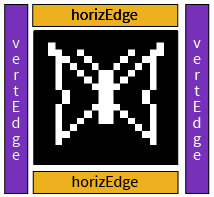

% Pad the edges all around with black
horizEdge = zeros([1 20]);
vertEdge = zeros([22 1]);
butterfly = [vertEdge [horizEdge;butterfly;horizEdge] vertEdge];
imshow(butterfly,"InitialMagnification",1000)

Oh no! The border is still there, because there is only one variable `butterfly` that is in use, and that didn't separate the border and the butterfly because the padding went outside the entire figure! 

% Set individual pixels to separate the butterfly from the border
butterfly(4,4) = 0;
butterfly(4,end-3) = 0;
imshow(butterfly,"InitialMagnification",1000)

Or maybe a couple more:

% Finish separating the butterfly from the border
butterfly(5,4) = 0;
butterfly(5,end-3) = 0;
imshow(butterfly,"InitialMagnification",1000)

This separated the butterfly from the border, but the border is now two pixels inside the edge rather than one.

One problem is that you have been redefining the matrix `butterfly` each time. If you simply reverse the order of the commands and first expand the matrix and then add the border it will look good and eliminating part of the butterfly won't be required to keep the components of the image distinct. Starting from the original butterfly image again:

butterfly = simpleIm2;
imshow(butterfly,"InitialMagnification",1000)

% Expand the matrix
horizEdge = zeros([1 20]);
vertEdge = zeros([22 1]);
butterfly = [vertEdge [horizEdge;butterfly;horizEdge] vertEdge];
imshow(butterfly,"InitialMagnification",1000)

% Add a border of white pixels one pixel inside the outer edge
butterfly(2,2:end-1) = 1;
butterfly(2:end-1,2) = 1;
butterfly(2:end-1,end-1) = 1;
butterfly(end-1,2:end-1) = 1;
imshow(butterfly,"InitialMagnification",1000)

** Exercise 4**.

Add some detail to the wings of the butterfly using indexing to address the pixel values you want to change. Remember that `1` is a white pixel and `0` is a black pixel. 

** Exercise 5**.

Start with the matrix

ex5 = [1 2 3; 5 6 7]

    a) Change the element `6` to be `13`. This means you should have `ex5 =` $\left[\matrix{ 1 & 2 & 3 \cr 5 & 13 & 7 }\right]$.

    b) Extract just the first row of the matrix and call it `row1ex5`. Thus, you should have `row1ex5 = `$\left[\matrix{1 & 2 & 3}\right]$.

    c) Append another row to create the matrix `ex5 = `$\left[\matrix{1 & 2 & 3 \cr 5 & 13 & 7 \cr 4 & 8 & 12}\right]$.

### Loading External Data

In most cases, the data that you want to analyze is going to be coming from outside of your immediate program. You will need to import the data so that your program can analyze it.

#### Files Related to the Programming Language

Any black and white image such as this mouse: 

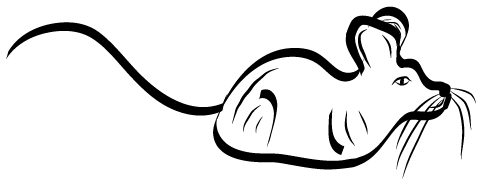

can be represented as a matrix of `1`'s and `0`'s. However, while it was relatively straightforward to design images on a small grid of a `20x20` matrix, this mouse is a `192x500` matrix. You probably do not want to carefully type each of those values, but you can import a matrix that contains them into your workspace.

% Import a data file that contains a black and white image of a mouse
% NOTE! If on a Windows machine, replace slash ('/') with backslash ('\')
load("Data/Mouse.mat")
mouse
imshow(mouse)

You can look at only a small piece of the mouse by indexing into the matrix. In this example, you see a `63x121` subsection cropped from `45` to `107` pixels horizontally and `350` to `470` pixels vertically. 

imshow(mouse(45:107,350:470))
annotatedMouse = mouse;
% Set a border just outside the selected region to highlight it in context
annotatedMouse([44 108],349:471) = 0;
annotatedMouse(44:108,[349 471]) = 0;
imshow(annotatedMouse)

** Exercise 5**.

    a) Create and display your own letter of the alphabet, `myLetter`:

myLetter = ...
   [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; ...
    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

    b) Starting from the blank matrix below, use indexing to recreate the letter shown in `simpleIm0`.

blank = zeros(20);

#### Standard File Types

You have probably encountered various image file types. For the rest of this script, you will be investigating a color photograph of turkeys that was saved in the standard image format of JPEG.

% Load an image of turkeys
% NOTE! If on a Windows machine, replace slash ('/') with backslash ('\')
picTurkeys = imread("Data/turkeys1.jpg");
% Split the RGB image into three channels each given by a matrix
% representing hue, saturation and value.  
hsvTurkeys = rgb2hsv(picTurkeys);
[h,s,v] = imsplit(hsvTurkeys);
montage([h;s;v])

Notice that `montage` has created a matrix of images! Not every matrix is so nice to visualize.

  **Try**. 

- In the argument to `montage()`, the matrices are concatenated vertically. What happens if you concatenate them horizontally?

- The original `picTurkeys` is an RGB image which stores values in terms of the amount of red, green, and blue required to display the complete image. If you use `imsplit()` on `picTurkeys` (rather than on `hsvTurkeys`) with output `[redChannel,greenChannel,blueChannel]` and then use `montage()` to display the result, do you get what you expect?

### Higher Dimensional Arrays

RGB images are 3-dimensional arrays, as they are made up of three 2-dimensional matrices. 

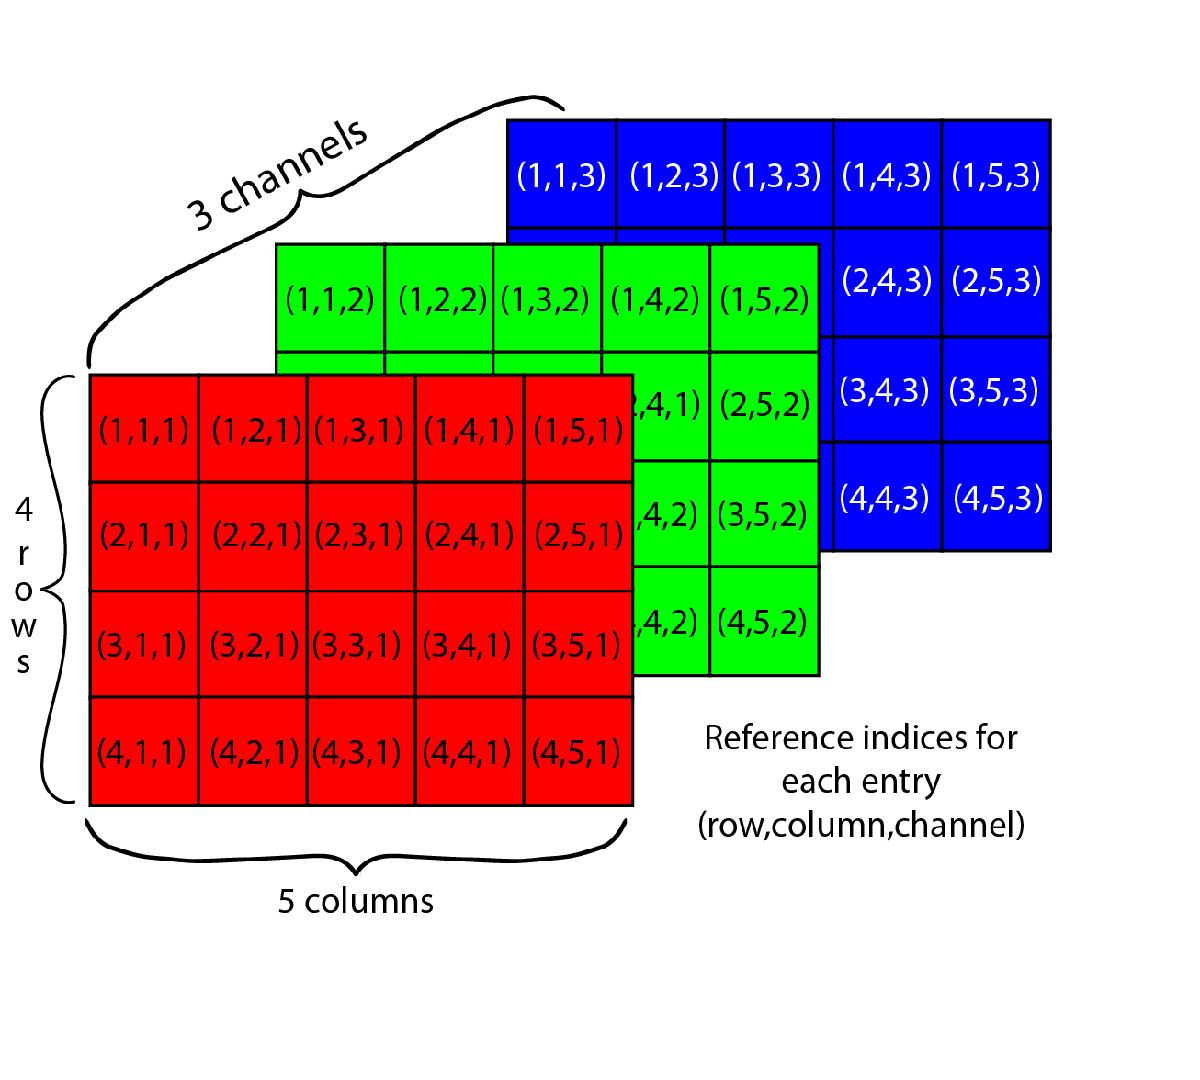

If you build a 3D array with the other channels being entirely `0`'s, you will be able to generate the expected results for `redChannel, greenChannel,` and `blueChannel` images.

Example:

[redChannel,greenChannel,blueChannel] = imsplit(picTurkeys);
noData = zeros(size(redChannel));
onlyRed = cat(3,redChannel,noData,noData);
imshow(onlyRed)

** Exercise 4**.

        a. Copy and modify the example code to display only the green channel `onlyGreen` and the blue channel `onlyBlue`.

        b. Check that your results are correct by running

        c. Invert the green channel by replacing `greenChannel` in the definition of `onlyGreen` with `255-greenChannel` since the values for each color range from `0` to `255`. Then display your result

 **Reflect**. 

- What constraints are there on structuring your data as a vector? a matrix? any other type of array?

- What are the benefits of structuring your data as a vector, matrix, or other array?

- Can you think of any reasons to avoid structuring your data as an array?

- What other structures would you like to use? Can you give any examples?

## Moving On

Now that you have gained some familiarity with data, it is time to consider how to leverage the power of computers to make controlled decisions about the instructions to run next in [Branches.mlx](matlab:open('./Branches.mlx')). 

[⇦ Overview](NavigationOverview.mlx)